# Simple script to generate DLV model data

clear;clc;

% Parameter setup and model invocation

param.N_neur = 256; % Number of “neurons” (binary units)
param.N_F = 4; % Number of latent fields hₘ(t)
param.tau_F = [0.3 1 3 10]; % Time constants (in seconds) for each OU field
%ones(1, param.N_F); % controls the time constants of the latents
param.T = 10; % Total simulation time (in seconds)

% ordered_J_if = randn(param.N_neur, param.N_F)/sqrt(param.N_F);
% ordered_J_if(1:64, 2:4) = 0;
% ordered_J_if(65:128, [1 3 4]) = 0;
% ordered_J_if(129:192, [1 2 4]) = 0;
% ordered_J_if(193:end, [1 2 3]) = 0;

param.fixJ_if = randn(param.N_neur, param.N_F)/sqrt(param.N_F); % ordered_J_if; %
param.eta_val = 3;
param.eps_val = 2.67*param.eta_val; % “Inverse temperature” and silence bias

[s_i, param, h_f] = sampleMorrellModel(param);

## Visualizing the Raw data and the latent variables

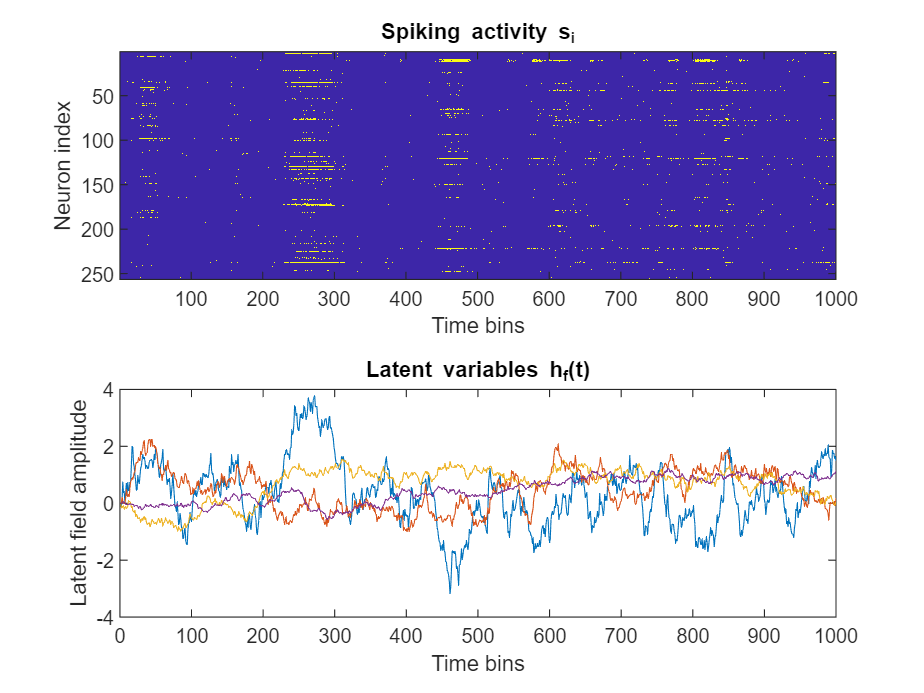

figure()
nexttile
imagesc(s_i)
xlabel('Time bins')
ylabel('Neuron index')
title('Spiking activity s_i')

nexttile
plot(h_f)
xlabel('Time bins')
ylabel('Latent field amplitude')
title('Latent variables h_f(t)')

## looking at PCA and relationship to ground truth (h_f, J_if)

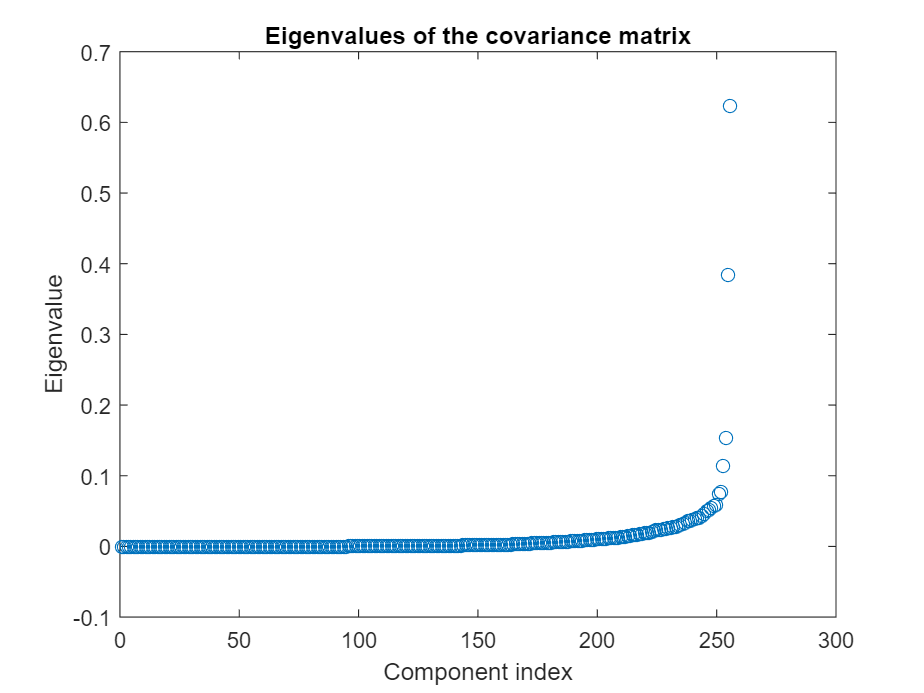

% getting the eigenvalues of covariance matrix
eig_vals = eig(cov(s_i'));
figure() 
plot(eig_vals, 'o')
xlabel('Component index')
ylabel('Eigenvalue')
title('Eigenvalues of the covariance matrix')

warning('off', 'MATLAB:rankDeficientMatrix')
s_centered = double(s_i) - mean(s_i,2);

[COEFF, SCORE, LATENT, TSQUARED, EXPLAINED, MU] = pca(s_centered);

num_comp = 150;
% Find how many PCs are needed to explain 85% variance
cum_explained = cumsum(EXPLAINED);
num_pcs_85percent = find(cum_explained >= 85, 1, 'first');

% Marchenko–Pastur threshold
[N, T] = size(s_centered);
Q = T / N;
sigma2 = mean(eig_vals);           % crude estimate of noise variance
lambda_max = sigma2 * (1 + sqrt(1/Q))^2;

% Find number of components above the MP threshold
num_sig_components = sum(eig_vals > lambda_max);
fprintf('Marchenko–Pastur suggests keeping %d PCs\n', num_sig_components);

Marchenko–Pastur suggests keeping 25 PCs


num_com_to_plot = 10;
time_points = linspace(1,param.T,1000);

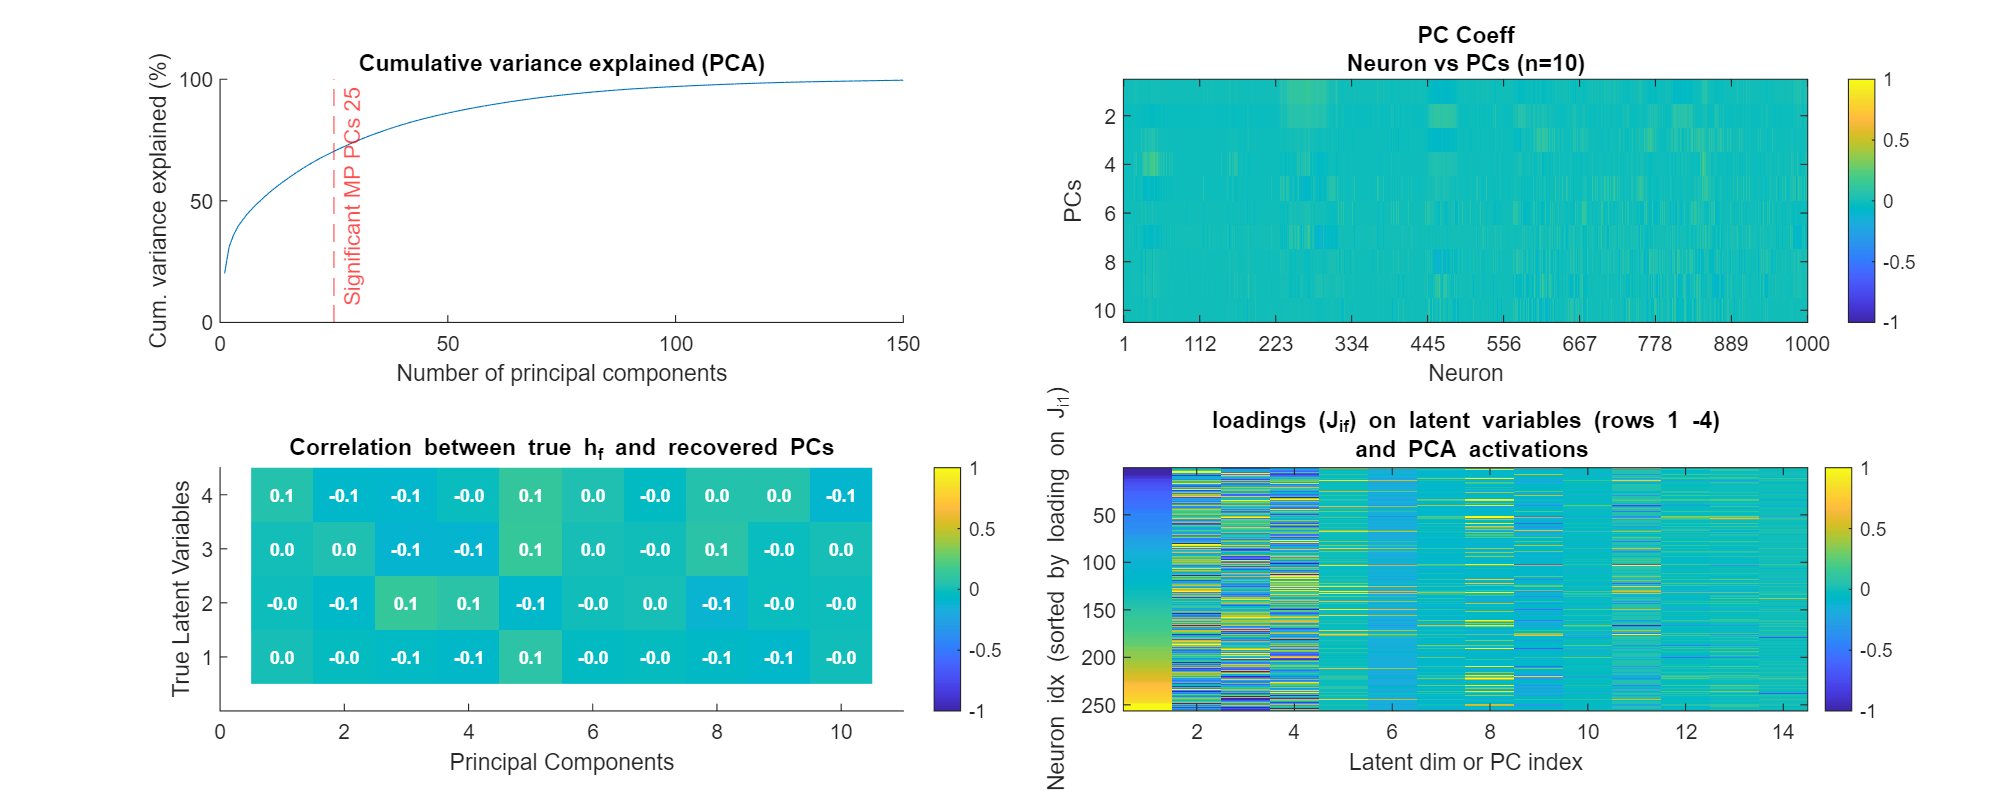

figure('Position', [100 100 2000 800]) 
nexttile
hold on;
plot(cum_explained)
xlim([0 150]);
ylim([0 100]);
xline(num_sig_components,'--r', ['Significant MP PCs ' num2str(num_sig_components)]);
xlabel('Number of principal components')
ylabel('Cum. variance explained (%)')
title('Cumulative variance explained (PCA)')

nexttile
imagesc(COEFF(:,1:num_com_to_plot)', [-1 1]);
title({'PC Coeff'; ['Neuron vs PCs (n=' num2str(num_com_to_plot) ')']});
xlabel('Neuron'); ylabel('PCs'); colorbar;
num_t_ticks = 10;
t_tick_idx = round(linspace(1, 1000, num_t_ticks));
t_tick_lbl = arrayfun(@(x) sprintf('%d', x*param.T/num_t_ticks), t_tick_idx, 'UniformOutput', false);
set(gca, 'XTick', t_tick_idx, 'XTickLabel', t_tick_lbl);

nexttile
% Correlation between latent fields and PCA activations
cc_mat = corrcoef([h_f(1:size(SCORE,1),:) SCORE(:, 1:num_com_to_plot)]);
cc_mat_sub = cc_mat(1:4, 5:end);
hold on;
imagesc(cc_mat_sub, [-1 1]); colorbar;
yticks(1:4);
xlim([0 num_com_to_plot+1]);
title('Correlation between true h_f and recovered PCs');
xlabel('Principal Components');
ylabel('True Latent Variables');
% Add numerical annotations
for i = 1:size(cc_mat_sub,1)
    for j = 1:size(cc_mat_sub,2)
        text(j, i, sprintf('%.2f', cc_mat_sub(i,j)), ...
            'HorizontalAlignment', 'center', ...
            'Color', 'w', 'FontSize',8, ...
            'FontWeight', 'bold');
    end
end
hold off;

nexttile
[~, ord1] =sort(param.fixJ_if(:, 1)); % Sorting the neurons by their true coupling to latent 1
% Showing side-by-side the true J_i,m versus the first 10 PCA oadings
% rescaled 
imagesc([param.fixJ_if(ord1, :) COEFF(ord1, 1:num_com_to_plot)*sqrt(param.N_neur/param.N_F)], [-1 1])
xlabel('Latent dim or PC index')
ylabel('Neuron idx (sorted by loading on J_{i1})')
title({['loadings (J_{if}) on latent variables (rows 1 -' num2str(param.N_F) ')']; ... 
    ' and PCA activations'}, 'interpreter', 'tex')
colorbar


% nexttile
% imagesc(cc_mat, [-1 1])
% xlabel('PCA components')
% ylabel('Latent variable index')
% title(['corr btw latent variables (rows 1-' num2str(param.N_F) ') and PCA activations'])
% colorbar



## Simulate a "readout" of the population activity and look at the power spectrum

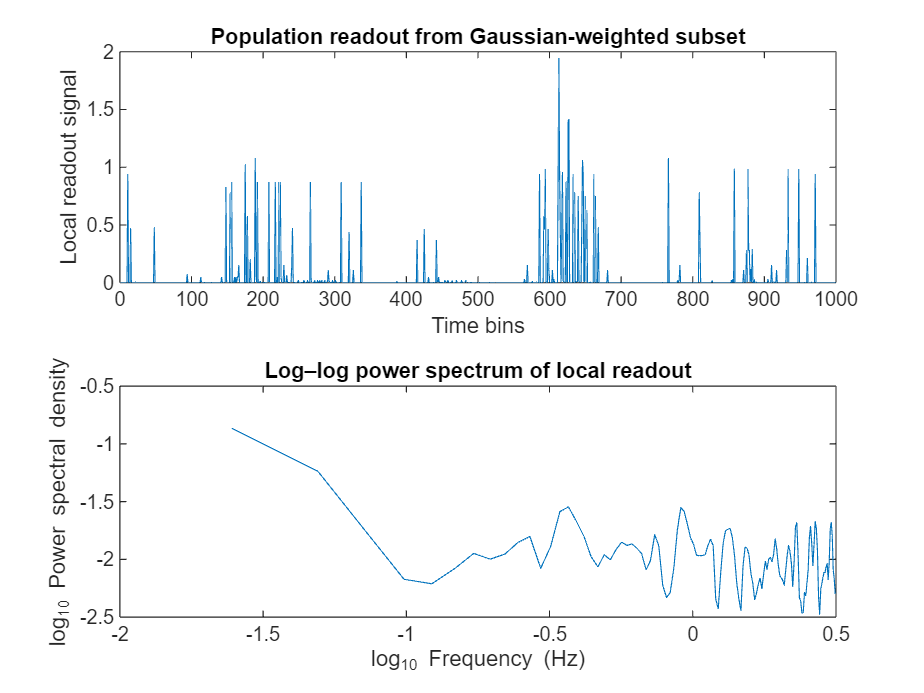

neuron_locations = 1:param.N_neur;
center_loc = 128;
nbhd_width = 32;
w_readout = exp(- (neuron_locations - center_loc).^2/(2*nbhd_width));

local_readout = w_readout*s_i;

figure()
nexttile
plot(local_readout)
xlabel('Time bins')
ylabel('Local readout signal')
title('Population readout from Gaussian-weighted subset')

[psd, f_psd] = pwelch(local_readout);
nexttile
plot(log10(f_psd), log10(psd))
xlabel('log_{10} Frequency (Hz)')
ylabel('log_{10} Power spectral density')
title('Log–log power spectrum of local readout')

% plot the latent vs. time and matched PC with time


## ICA Test

% PCA assumes uncorrelated Gaussian mixtures, but my latent fields are
% non-Gaussian OU processes. 

% let's assume each neuron is a channel
EEG_data = double(s_i); % ch x time

% 2. Manually build a minimal EEG structure
EEG = eeg_emptyset();
EEG.data   = EEG_data;
EEG.nbchan = size(EEG.data, 1);   % number of "channels" = neurons
EEG.pnts   = size(EEG.data, 2);   % number of time points
EEG.trials = 1;                   % continuous data
EEG.srate  = 100;                 % arbitrary sample rate (adjust if needed)
EEG.xmin   = 0;
EEG = eeg_checkset(EEG);

eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


% Run ICA without PCA
EEG = pop_runica(EEG, 'extended', 1, 'interrupt', 'off');

Attempting to convert data matrix to double precision for more accurate ICA results.
Data rank (171) is smaller than the number of channels (256).



Input data size [171,1000] = 171 channels, 1000 frames/nAfter PCA dimension reduction,
  finding 171 ICA components using extended ICA.
Kurtosis will be calculated initially every 1 blocks using 1000 data points.
Decomposing 0 frames per ICA weight ((29241)^2 = 1000 weights, Initial learning rate will be 0.001, block size 35.
Learning rate will be multiplied by 0.98 whenever angledelta >= 60 deg.
More than 32 channels: default stopping weight change 1E-7
Training will end when wchange < 1e-07 or after 512 steps.
Online bias adjustment will be used.
Removing mean of each channel ...
Final training data range: -0.163 to 0.999
Reducing the data to 171 principal dimensions...
Computing the sphering matrix...
Starting weights are the identity matrix ...
Sphering the data ...
Beginning ICA training ... first training step may be slow ...
Lowering learning rate to 0.0009 and starting again.
Lowering learning rate to 0.00081 and starting again.
Lowering learning rate to 0.000729 and starting 

% The ICA activations (component time courses)
icasig = EEG.icaact;      % size: components × time
icasig = real(icasig);

A = EEG.icawinv;          % unmixing matrix: channels × components
W = EEG.icaweights;       % weights (unmixing) matrix

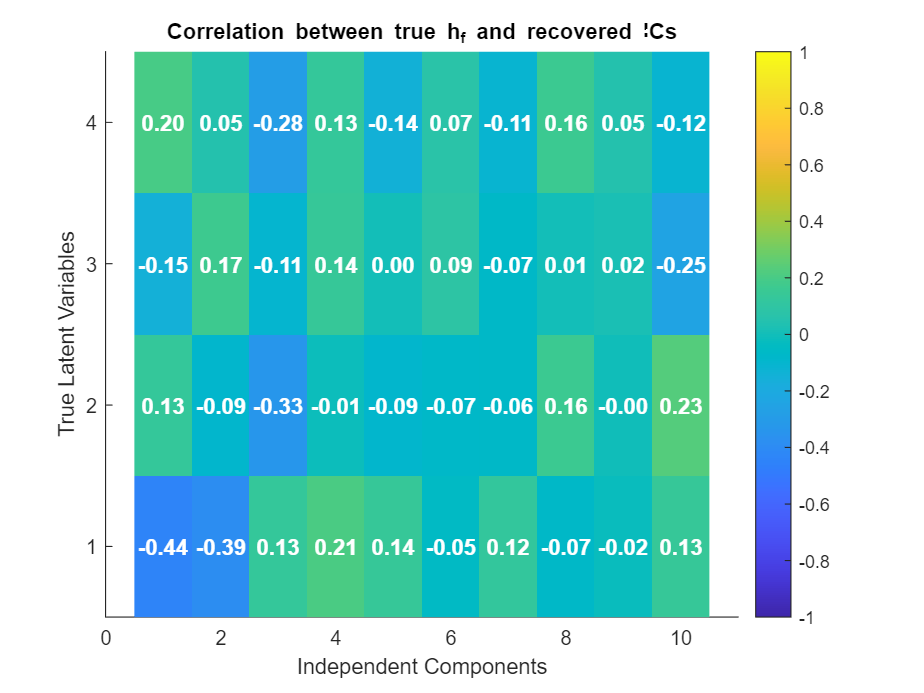

R = corrcoef([h_f, icasig']);
R_sub = R(1:4, 5:14);

figure()
hold on;
imagesc(R_sub, [-1 1]); 
colorbar;
yticks(1:4);
xlim([0 11]);
title('Correlation between true h_f and recovered ICs');
xlabel('Independent Components');
ylabel('True Latent Variables');
% Add numerical annotations
for i = 1:size(R_sub,1)
    for j = 1:size(R_sub,2)
        text(j, i, sprintf('%.2f', R_sub(i,j)), ...
            'HorizontalAlignment', 'center', ...
            'Color', 'w', ...
            'FontWeight', 'bold');
    end
end
hold off;